**EXCERCISE 1: DEFINITION OF PROBABILITY:**

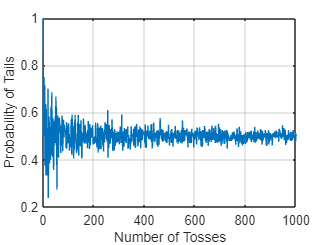

numTossesRange=1:1000;

probability=zeros(size(numTossesRange));

for i=1:numel(numTossesRange)
    numTosses=numTossesRange(i);

    results=randi([0,1],1,numTosses);

    numTails=sum(results==1);
    probability(i)=numTails/numTosses;
end

plot(numTossesRange,probability);
xlabel('Number of Tosses');
ylabel('Probability of Tails');
grid on;